初版：2021年12月18日

# シミュレーション　講義ノート No.4

#### 藤原　哉

#### 農林中央金庫

## 確率過程のシミュレーション

### 1. ランダムウォーク

　ランダムウォークは、ベルヌーイ試行の累積和であり最も基本的な確率過程である。

・ランダムウォークの定義

確率過程 $Z_t$がランダムウォークであるとは $p \in (0,1),\Delta  \gt 0$としてベルヌーイ試行を $\xi_i$と表すと


$$\mathbb{P}(\xi_i = \Delta ) = p, \ \ \mathbb{P}(\xi_i = -\Delta) = 1-p$$



$$Z_0 = 0, \ \ Z_t = \xi_1 + \cdots + \xi_t$$


を満たすことである。ただし、 $\xi_1, \cdots, \xi_t$は独立である。 $p=\frac{1}{2}$のときは対称ランダムウォークと呼ばれる。

ランダムウォークのシミュレーション例を示す。 $p=\frac{1}{2}, \Delta = 1$としている。

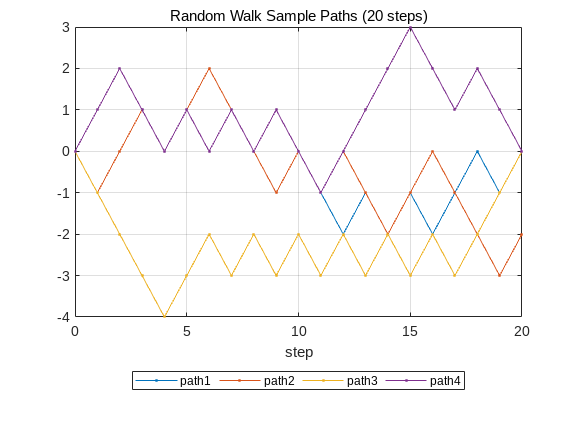

clear; 

% ベルヌーイ試行を生成する関数
genXi = @(nSteps,nPaths) 2*(randi(2,nSteps,nPaths)-1) - 1 ; 

% ランダムウォークを生成する関数
genRandomWalkPaths = @(nSteps,nPaths) cumsum([zeros(1,nPaths);genXi(nSteps,nPaths)]);

nSteps = 20; 
nPaths = 4; 
rwPaths = genRandomWalkPaths(nSteps,nPaths);

nfig = 1; 
figure(nfig);plot(0:nSteps,rwPaths','.-');grid;
title('Random Walk Sample Paths (20 steps)'); xlabel('step'); 
legend('path1','path2','path3','path4','location','southoutside','Orientation',"horizontal");

ランダムウォークの定義は単純であるが数多くの面白い性質が知られている。

いくつかシミュレーションで確認する。

#### 最大値の分布

対称ランダムウォーク $Z_t$のステップ数を $T$とし、 $\{Z_0, Z_1,\cdots, Z_T\}$での最大値を $M_T = \max_{t \in [0,T]} Z_t$と定義する。

このとき、最終ステップ $Z_T$の値が $a$であり最大値 $M_T$の値が $k$以上となる確率 $\mathbb{P}\left( \{Z_T = a \} \cap \{M_T \ge k \} \right)$は最終ステップでの $Z_T$の分布確率で表現され

 
$$\mathbb{P}\left( \{Z_T = a \} \cap \{M_T \ge k \} \right) = \mathbb{P}\left( \{Z_T = 2k-a\} \right)$$


となることが知られている。下のサンプルパスでは $Z_T = -2, M_T = 1$である。

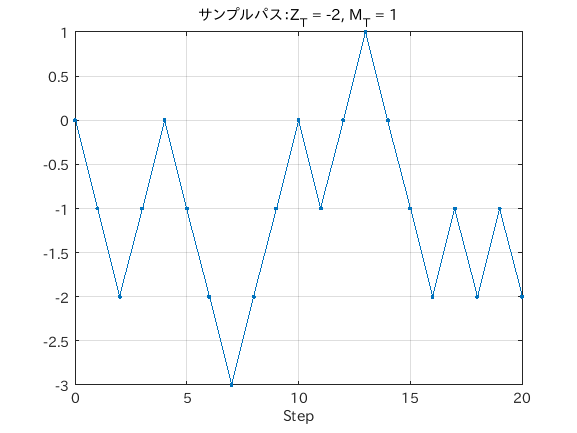

rng('default');
nSteps = 20;
pt = genRandomWalkPaths(nSteps,nPaths); 
nfig = 2; 
figure(nfig); plot(0:nSteps,pt(:,3),'.-');grid; title("サンプルパス：Z_T = -2, M_T = 1"); xlabel('Step');  

最大値の分布式の左辺は経路依存（最大値に依存）であるが、右辺は最終時点の分布だけに依存するため直観的に成り立つことを理解することは難しい。

証明は割愛（参考文献で示されている）し、ここではモンテカルロ・シミュレーションで、この関係が成り立っていることを確認する。

ステップ数を $T=20$として, $a=0, k=1$のとき、つまり $Z_T = 0, M_T \ge 1$となる確率をシミュレーションで算出する。

解析解は $\mathbb{P}\left( \{Z_{20} = 2\cdot1-0 = 2\} \right) = \pmatrix{20 \cr 11} \cdot \left( \frac{1}{2} \right)^{20} \simeq 0.1602$である。

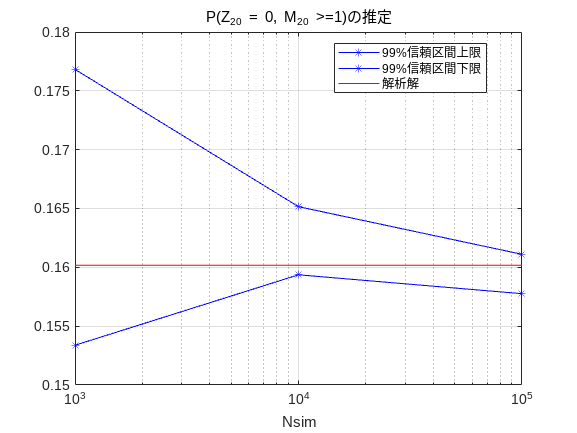

nSteps = 20; % Tの値
a = 0; %Z_Tの値
k = 1; % M_Tの値

Nsims = [1000;10000;100000];
lowersIto = zeros(size(Nsims));
uppersIto = lowersIto; 

Nt = 10; 
alp = 0.01;

for iloop = 1:size(Nsims,1)
    vs = zeros(Nt,1);
    Nsim = Nsims(iloop); 
    for jloop = 1:Nt
        % ランダムウォークのパス生成
        paths = genRandomWalkPaths(nSteps,Nsim);
        % Z_T = aとなるパスの抽出
        paths = paths(:,eq(paths(end,:),a));
        % Z_T = a AND M_T >= k となるパスの数の比率
        vs(jloop,1) = sum(ge(max(paths),k))/Nsim;
    end
    %信頼区間の算出
    rsts = estConfidenceInterval(vs,alp);
    lowersIto(iloop) = rsts.CILower;
    uppersIto(iloop) = rsts.CIUpper; 
end

% 解析解
pana = nchoosek(nSteps,(nSteps+2*k)/2)*(1/2)^20;
nfig = 3; 
figure(nfig); semilogx(Nsims,[uppersIto,lowersIto],'b*-'); grid; title("P(Z_{20} = 0, M_{20} >=1)の推定"); xlabel("Nsim"); hold on; 
semilogx(Nsims,pana*ones(size(Nsims)),'r-'); legend("99%信頼区間上限","99%信頼区間下限","解析解","Location","best"); hold off;  

#### 初期到達時刻

$Z_0 = 0$から出発したランダムウォークが初めてある値aへ到達するステップ(時間）を初期到達時刻といい $\tau_a = \inf\left\{ t \vert Z_t = a \right\}$と表す。

下の例では $a=1$に初めて到達するのは13ステップ目なので $\tau_1 = 13$となる。

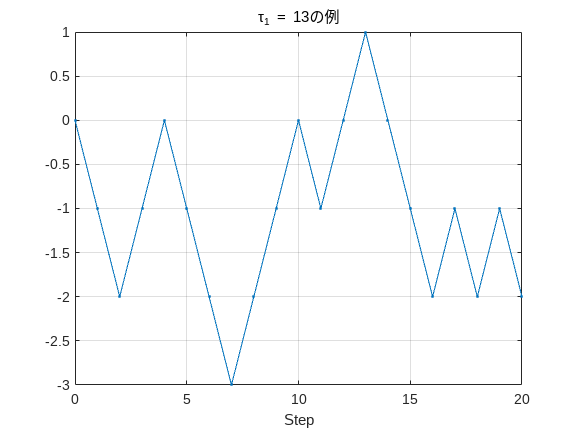

nfig = 4; 
figure(nfig); plot(0:nSteps,pt(:,3),'.-');grid; title("\tau_1 = 13の例"); xlabel('Step'); 

$\tau_a$の確率分布については以下の関係が知られている。


$$\mathbb{P}(\tau_a = k) = \frac{|a|}{k}\mathbb{P}(Z_k = a), \ a \ne 0$$


これより、時点９で初めて１に到達する確率 $\mathbb{P}(\tau_1 = 9)}$は,  $\frac{1}{9} \mathbb{P}(Z_9 = 1) = \frac{1}{9} \pmatrix{9 \cr 5} \left( \frac{1}{2} \right)^{9} \simeq 0.0273$と計算できる。

以下ではシミュレーション回数を1000回として $\mathbb{P}(Z_1 = 1),\mathbb{P}(Z_1 = 3),\mathbb{P}(Z_1 = 5), \mathbb{P}(Z_1 = 7), \mathbb{P}(Z_1 = 9)$ を推定する。

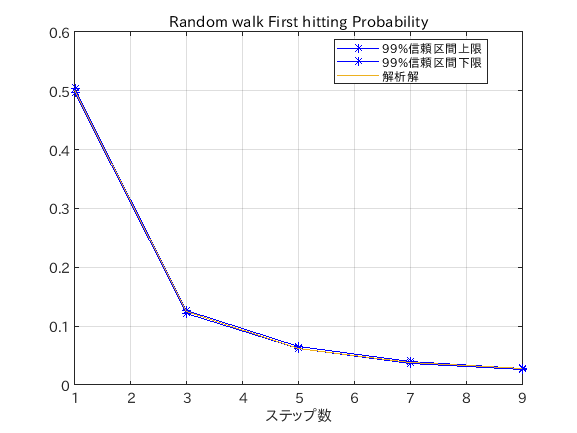


nStepss = 2*(1:5)'-1; 
a = 1; 

Nsim = 1000; 
Nt = 100; 
alp = 0.01; 

lowers = zeros(size(nStepss));
uppers = zeros(size(nStepss)); 
for iloop = 1:size(nStepss,1)
    nSteps = nStepss(iloop);
    vs = zeros(Nt,1);
    for jloop = 1:Nt
        sPaths = genRandomWalkPaths(nSteps,Nsim);
        sPaths = sPaths(1:end-1,eq(sPaths(end,:),a)); % 最終ステップでaとなるパスを抽出
        [~,ntmp] = size(sPaths); %抽出されたパス数
        sPaths(eq(sPaths,a)) = 1; %最終ステップ前にaに到達している箇所を１
        sPaths(not(eq(sPaths,a))) = 0; %最終ステップ前のa以外の箇所を0
        vs(jloop) = (ntmp - sum(sum(sPaths)>0))/Nsim; % sum(sum(sPaths)>0)は最終ステップ以前に aに到達したパス数
    end
    rst = estConfidenceInterval(vs,alp);
    lowers(iloop) = rst.CILower; 
    uppers(iloop) = rst.CIUpper; 
end
pfun = @(n) abs(a)./(2*n-1).*nchoosek(2*n-1,n).*(1/2).^(2*n-1);
pana = arrayfun(pfun,(1:5)'); 

nfig = 5; 
figure(nfig); 
plot(nStepss,[uppers,lowers],'b*-'); grid; title('Random walk First hitting Probability'); xlabel('ステップ数'); hold on; 
plot(nStepss,pana,'-'); legend('99%信頼区間上限','99%信頼区間下限','解析解','Location','best'); 
hold off; 

### 2. ブラウン運動

　ブラウン運動は連続な確率過程の基本である。ブラウン運動はランダムウォークの極限として表現される。

時間ステップ幅を $\Delta t$として $\mathbb{P}\left( \xi_i = \sqrt{\Delta t} \right) = \mathbb{P} \left( \xi_i = -\sqrt{\Delta t} \right) = \frac{1}{2}$とする。


$$W_t = \sum_{i=1}^n \xi_i$$



$$t = n \Delta t$$


とし, $t$を一定として $\Delta t \rightarrow 0, \ n \rightarrow \infty$とすると $W_t$はブラウン運動となる。 

$\mathbb{E}\left[\xi i \right]  = 0, \ {\rm Var}\left[ \xi_i \right] = \Delta t$であり $\{\xi_i\}$は独立であるので、中心極限定理より


$$\frac{W_t}{\sqrt{n} \sqrt{\Delta t}} \sim N(0,1), \ {\rm as} \ n \rightarrow \infty$$


となるので、 $W_t \sim N(0,t)$となることがわかる。

時間間隔が１か月 $\Delta t = \frac{1}{12}$、１週間 $\Delta t = \frac{1}{48}$、２日 $\Delta t = \frac{1}{120}$、１日 $\Delta t = \frac{1}{240}$のときの1年のランダムウォークのパスを示す。

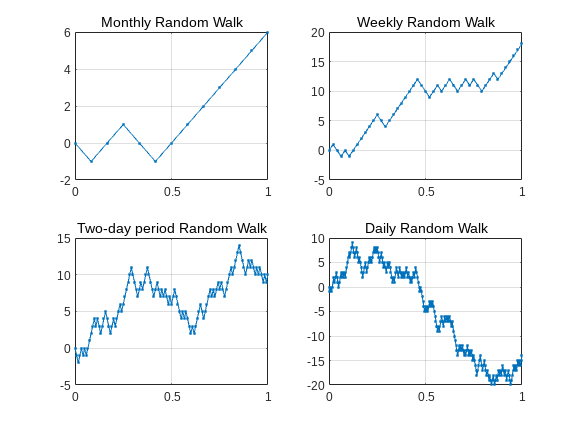

%　ランダムウォークによるブラウン運動の近似
genBMPathfromRW = @(T,nSteps,nPaths) genRandomWalkPaths(nSteps,nPaths).*sqrt(T/nSteps);

T = 1; 
mkGraph = @(nSteps) plot(0:T/nSteps:T,genRandomWalkPaths(nSteps,1),'.-');  

nfig = 6;
figure(nfig);subplot(221);mkGraph(12);grid; title('Monthly Random Walk'); 
figure(nfig);subplot(222);mkGraph(48);grid; title('Weekly Random Walk');
figure(nfig);subplot(223);mkGraph(120);grid; title('Two-day period Random Walk');
figure(nfig);subplot(224);mkGraph(240);grid; title('Daily Random Walk'); 

ブラウン運動の定義は

- 
$$W_0 = 0$$


- 
$$W_t - W_s \sim N(0,t-s)$$


- $W_s$と $W_t - W_s$は独立（独立増分）

- $W_t$は連続

である。ブラウン運動の定義に従うと時刻 $t_0, t_1,t_2,\cdots,t_N$でのサンプルパスは次のように生成できる。


$$W_{t_0} = 0$$



$$W_{t_i} = W_{t_{i-1}} + \sqrt{t_i - t_{i-1}} \ \varepsilon_{t_{i}}$$



$$\varepsilon_t \sim N(0,1)$$


これより、時間間隔が１か月 $\Delta t = \frac{1}{12}$、１週間 $\Delta t = \frac{1}{48}$、２日 $\Delta t = \frac{1}{120}$、１日 $\Delta t = \frac{1}{240}$のときの1年のブラウン運動のサンプルパスを示す。

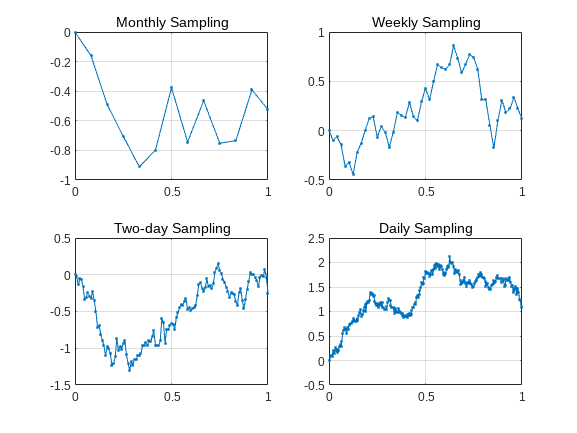

% ブラウン運動のサンプルパス
genBWpaths = @(dt,nSteps,nPaths) cumsum([zeros(1,nPaths);sqrt(dt)*randn(nSteps,nPaths)],1);

T = 1; 
mkGraph = @(nSteps) plot(0:T/nSteps:T,genBWpaths(T/nSteps,nSteps,1),'.-');  
nfig = 7; 
figure(nfig);subplot(221);mkGraph(12);grid; title('Monthly Sampling'); 
figure(nfig);subplot(222);mkGraph(48);grid; title('Weekly Sampling');
figure(nfig);subplot(223);mkGraph(120);grid; title('Two-day Sampling');
figure(nfig);subplot(224);mkGraph(240);grid; title('Daily Sampling'); 

ブラウン運動はランダムウォークの極限であるためランダムウォークと同様の性質をもつ。

いくつかをシミュレーションで確かめる。

**最大値の分布**

$[0,T]$でのブラウン運動 $W_t$の最大値を$M_T = \sup_{t \in [0,T]} \left(W_t \right)$とする。任意の $y \ge 0, \ x \le y$に対して、最大値 $M_T$がyより大きく、ブラウン運動の$T$での値が x以下である確率は 


$$\mathbb{P}\left( \{ W_T \le x\} \cap \{M_T \gt y \} \right) = \mathbb{P}\left( \{ W_T \ge 2y - x \} \right)$$


と表される。ランダムウォークの時と同様に左辺は経路依存( $M_T$)であるが、右辺は $T$での値だけの関数となる。

$T = 1$として $x = 0, y = 1$での最大値の分布確率は右辺より解析的に計算でき $\mathbb{P} \left( W_1 \ge 2) \simeq 0.0228$となる。 

**注意**


$${\bf ランダムウォークと違いブラウン運動は連続である。よって、シミュレーションでのサンプリングは離散近似となる。そのため誤差（バイアス）が生じることになる。}$$



$${\bf 特に、最大値の問題のように連続時間での経路依存を含む場合には注意が必要となる。}$$



$${\bf シミュレーションで、離散近似誤差の影響を確認する。この例では最大値を離散近似で求めているため過少評価となっている。1年間の分割数を10000程度にしないと離散化誤差の影響を無視できないことがわかる。}$$


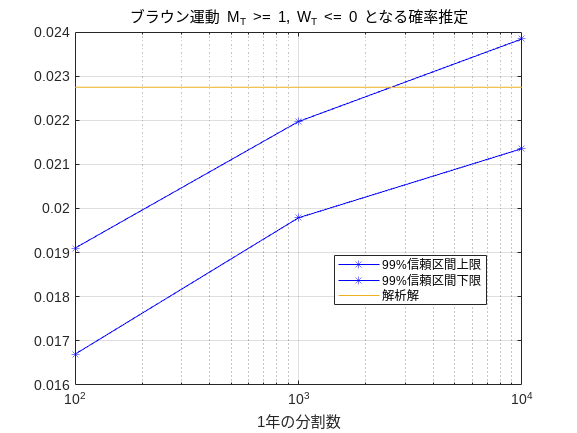

% 最大値の分布確率計算
% 離散近似による誤差の影響確認

T = 1; % 期間は1年
x = 0 ;% W_T <= 0 
y = 1 ;% M_T >= 1 

nStepss = [100; 1000; 10000]; % 1年あたりのサンプリング数

Nsim = 1000; % サンプルパスの数
Nt = 100; % 信頼区間推定用の繰り返し回数
alp = 0.01; % 信頼区間水準

lowersIto = zeros(size(nStepss));
uppersIto = lowersIto; 

for iloop = 1:size(nStepss,1)
    nSteps = nStepss(iloop);
    vs = zeros(Nt,1);
    for jloop = 1:Nt
        % ブラウン運動　サンプリング
        ws = genBWpaths(T/nSteps,nSteps,Nsim);
        % W_T <= x となるパスの抽出
        ws = ws(:,le(ws(end,:),x));
        % M_T >= 1 and W_T <= xとなるパスの比率
        vs(jloop,1) = sum(ge(max(ws),y))/Nsim; 
    end
    rst = estConfidenceInterval(vs,alp);
    lowersIto(iloop) = rst.CILower;
    uppersIto(iloop) = rst.CIUpper; 
end
pana = 1 - normcdf(2*y-x); 

nfig = 8;
figure(nfig); semilogx(nStepss,[uppersIto,lowersIto],'b*-'); grid; title("ブラウン運動 M_T >= 1, W_T <= 0 となる確率推定"); xlabel("1年の分割数"); hold on; 
semilogx(nStepss,pana*ones(size(nStepss)),'-'); legend("99%信頼区間上限","99%信頼区間下限","解析解","Location","best"); hold off;  

#### 初期到達時刻

ランダムウォークと同様にブラウン運動でも $W_0 = 0$から出発して $a>0$に到達する最初の時刻を $\tau_a = \inf \left( t \vert W_t \ge a)$とすると、

時刻tまでに $a$に到達する確率は $\mathbb{P}\left( \tau_a \le t \right) = 2 N \left( - \frac{a}{\sqrt{t}} \right)$となる。

$a = 1$として時刻 $t=1$までに $W_t$が $a=1$に到達する確率をシミュレーションで算出して解析解と比較する。

ブラウン運動は連続な確率過程であるので、離散近似の離散幅の影響を受ける。特にこの問題のように経路依存性が強い場合には離散幅の影響を大きく受けるので注意が必要である。

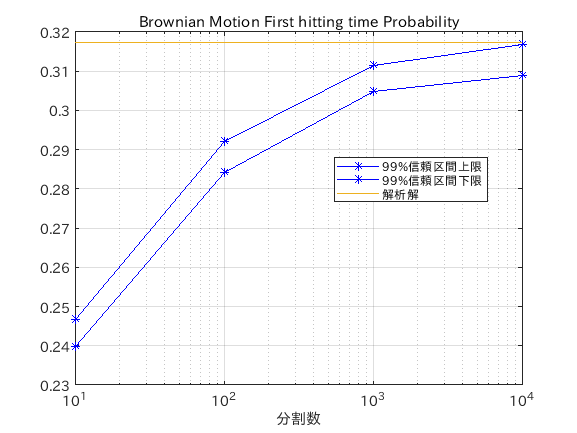

T = 1; 
a = 1; 

Nsim = 1000; 
Nt = 100; 
alp = 0.01; 

nStepss = [10;100;1000;10000];
uppers = zeros(size(nStepss));
lowers = zeros(size(nStepss));

for iloop = 1:size(nStepss,1)
    nSteps = nStepss(iloop);
    vs = zeros(Nt,1);
    for jloop = 1:Nt
        ws = genBWpaths(T/nSteps,nSteps,Nsim); 
        vs(jloop) = sum(ge(max(ws),a))/Nsim; 
    end
    rst = estConfidenceInterval(vs,alp);
    uppers(iloop) = rst.CIUpper;
    lowers(iloop) = rst.CILower; 
end

nfig = 9; 
figure(nfig);
semilogx(nStepss,[uppers,lowers],'b*-'); grid; xlabel('分割数'); title("Brownian Motion First hitting time Probability"); 
hold on; 
semilogx(nStepss,2*normcdf(-a/sqrt(T))*ones(size(nStepss)),'-'); 
legend('99%信頼区間上限','99%信頼区間下限','解析解','Location','best');
hold off; 

#### 3. Ito積分とStratonovich積分

ブラウン運動に関する積分にはIto積分とStratonovich積分がある。

Ito積分は被積分関数を $f_t$とすると


$$\int_t^T f_s {\rm d}W_s = \lim_{n \rightarrow \infty}{ \sum_{i=0}^{n-1} f_{t_i} \times \left(W_{t_{i+1}} - W_{t_i} \right)}$$



$$t_i = t + \frac{T-t}{n} i$$


と定義される。区間 $[t_i, t_{i+1}]$での左端での関数値 $f_{t_i}$を用いている。また、離散近似は


$$\int_t^T f_s {\rm d}W_s \simeq  \sum_{i=0}^{n-1} f_{t_i} \times \left(W_{t_{i+1}} - W_{t_i} \right)$$


となる。

Stratonovich積分は次のように定義される。Stratonovich積分であることを示すために $\circ$を用いている。


$$\int_t^T f_s \circ {\rm d}W_s = \lim_{n \rightarrow \infty} \sum_{i=0}^{n-1} f_{\frac{t_{i+1} + t_{i}}{2}} \times \left( W_{t_{i+1}} - W_{t_i} \right)$$


区間 $[t_i, t_{i+1}]$での中点での関数値 $f_{\frac{t_{i+1} + t_i}{2}}$を用いている。離散近似は


$$\int_t^T f_s \circ {\rm d}W_s \simeq \sum_{i=0}^{n-1} f_{\frac{t_{i+1} + t_i}{2}} \times \left( W_{t_{i+1}} - W_{t_i} \right)$$


となる。Ito積分とStratonovich積分の違いのイメージを下図に示す。

Ito積分イメージ

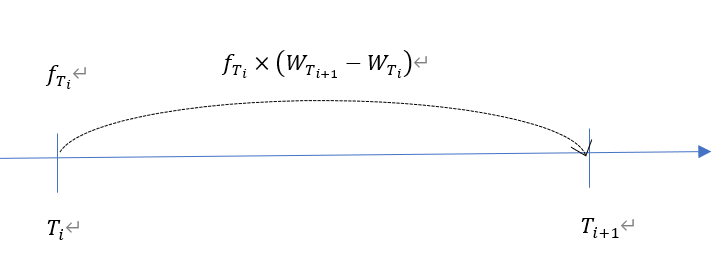

Stratonovich積分イメージ

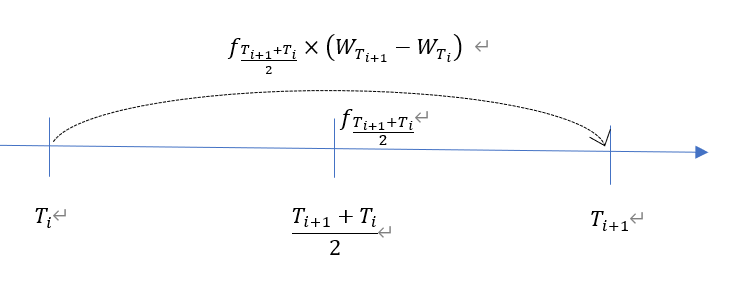

Ito積分、Stratonovich積分はパスごとの積分であるため積分値は確率変数であることに注意する。

例として $f_t = W_t$とする。このときIto積分は$\int_0^1 W_s {\rm d}W_s = \frac{1}{2}W_1^2 - \frac{1}{2}$、Stratonovich積分は $\int_0^1 W_s \circ {\rm d}W_s = \frac{1}{2}W_1^2$となることが知られている。

よって、期待値は $\mathbb{E}\left[W_1^2 \right] = 1$であるので


$$\mathbb{E}\left[ \int_0^1 W_s {\rm d }W_s\right] = 0$$


 
$$\mathbb{E}\left[ \int_0^1 W_s \circ {\rm d}W_s \right] = \frac{1}{2}$$


となる。

 $\mathbb{E}\left[ \int_0^1 W_s {\rm d }W_s\right],\  \mathbb{E}\left[ \int_0^1 W_s \circ {\rm d}W_s \right]$を離散近似を用いてシミュレーションで評価して期待値である $0, \frac{1}{2}$と比較する。

連続の問題を離散近似で評価するため離散誤差が生じることになるが、この例では離散誤差の影響はあまりない。

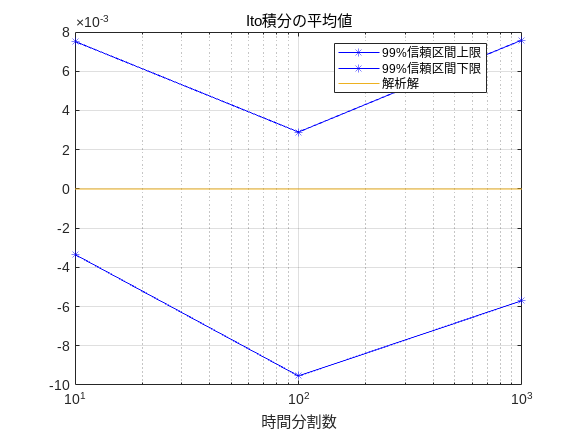

% Ito積分とStratonovich積分の期待値計算

T = 1; 

nStepss = [10;100;1000]; %時間の分割数

Nsim = 1000; % サンプルパスの数
Nt = 100; % 信頼区間推定用の繰り返し回数
alp = 0.01; % 信頼区間水準

lowersIto = zeros(size(nStepss));
uppersIto = lowersIto; 
lowersStratonovich = zeros(size(nStepss));
uppersStratonovich = lowersStratonovich; 

for iloop = 1:size(nStepss,1)
    nSteps = nStepss(iloop);
    vsIto = zeros(Nt,1);
    vsStratonovich = zeros(Nt,1);
    for jloop = 1:Nt
        % ブラウン運動　サンプリング
        ws = genBWpaths(T/(2*nSteps),2*nSteps,Nsim);
        % 被積分関数、ブラウン運動の増分
        fIto = ws(1:2:end-2,:);
        fStratonovich = ws(2:2:end,:); 
        dw = diff(ws(1:2:end,:)); 
        % 積分近似
        vsIto(jloop,1) = mean(sum(fIto.*dw)); 
        vsStratonovich(jloop,1) = mean(sum(fStratonovich.*dw)); 
    end
    % Ito積分の上下限
    rst = estConfidenceInterval(vsIto,alp);
    lowersIto(iloop) = rst.CILower;
    uppersIto(iloop) = rst.CIUpper; 
    % Stratonovich積分の上下限
    rst = estConfidenceInterval(vsStratonovich,alp);
    lowersStratonovich(iloop) = rst.CILower;
    uppersStratonovich(iloop) = rst.CIUpper; 
end

nfig = 10;
figure(nfig); semilogx(nStepss,[uppersIto,lowersIto],'b*-'); grid; title("Ito積分の平均値"); hold on; 
semilogx(nStepss,zeros(size(nStepss)),'-'); 
legend("99%信頼区間上限","99%信頼区間下限","解析解","Location","best"); xlabel("時間分割数"); hold off;

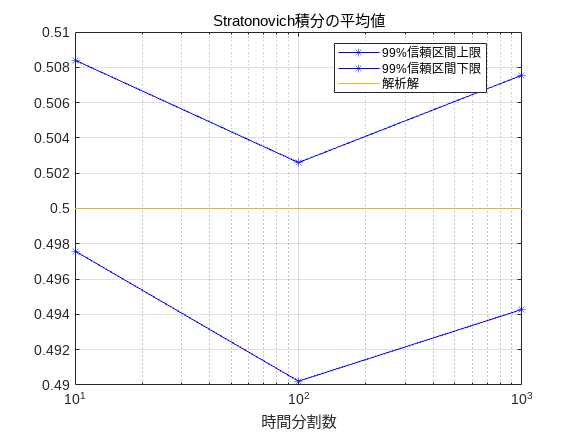

nfig = 11;
figure(nfig); semilogx(nStepss,[uppersStratonovich,lowersStratonovich],'b*-'); grid; title("Stratonovich積分の平均値"); hold on; 
semilogx(nStepss,0.5*ones(size(nStepss)),'-'); legend("99%信頼区間上限","99%信頼区間下限","解析解","Location","best"); xlabel("時間分割数"); hold off; 

### 4. 確率微分方程式のシミュレーション

確率変動をモデル化するときに確率微分方程式を用いることが多い。確率微分方程式は解析的に解くことができるパターンは限られており、離散近似により数値的に評価することになる。

確率微分方程式の離散化は常微分方程式の離散化と考え方は同じであるので、最初に常微分方程式の離散化の方法を確認する。

#### 常微分方程式の離散化

　解くべき常微分方程式を ${\rm d}x = \mu(t,x_t) {\rm d} t$とする。この方程式の解は $x_t$を所与とすると形式的に


$$x_{t+\Delta t} = x_t + \int_{t}^{t+\Delta t} \mu(s,x_s) {\rm d} s$$


となる。最も単純な方法は $[t,t+\Delta t]$において $\mu(t,x_t)$は一定と仮定することである。この場合は


$$x_{t+\Delta t} = x_t + \mu(t,x_t) \Delta t$$


となる。この方法はEuler法と呼ばれている。

Euler法は簡単であるが精度があまり良くない。精度を上げるために、形式的な解の被積分関数  $\mu(s,x_s)$を $(t,x_t)$周りで1次のテーラー展開をすると


$$\mu(s,x_s) = \mu(t,x_t) + \frac{\partial }{\partial t} \mu(t,x_t) (s-t) + \frac{\partial }{\partial x} \mu(t,x_t) (x_s - x_t) \simeq \mu(t,x_t) + \left( \frac{\partial}{\partial t} \mu(t,x_t) + \mu(t,x_t) \frac{\partial}{\partial x} \mu(t,x_t) \right) (s-t)$$


となる。ただし、 $x_s - x_t \simeq \mu(t,x_t) (s-t)$とEuler法で近似している。この式を形式的な解の式に代入すると


$$x_{t+\Delta t} = x_t + \mu(t,x_t) \int_{t}^{t+\Delta t} {\rm d}s + \left( \frac{\partial}{\partial t} \mu(t,x_t) + \mu(t,x_t) \frac{\partial}{\partial x} \mu(t,x_t) \right) \int_{t}^{t+\Delta t} (s-t) {\rm d} s$$



$$= x_t + \mu(t,x_t) \Delta t + \left( \frac{\partial}{\partial t} \mu(t,x_t) + \mu(t,x_t) \frac{\partial}{\partial x} \mu(t,x_t) \right) \frac{\Delta t^2}{2}$$


となる。 $x_0$が与えられていて $x_T$を求める場合には区間 $[0,T]$を $[0,\Delta t , 2\Delta t , \cdots , N \Delta t = T]$と分割して


$$x_{n \Delta t }= x_{(n-1)\Delta t} + \mu \left((n-1)\Delta t, x_{(n-1)\Delta t}\right) \Delta t + \left( \frac{\partial}{\partial t} \mu\left( (n-1)\Delta t,x_{(n-1) \Delta t} \right) + \mu\left( (n-1)\Delta t,x_{(n-1) \Delta t} \right) \frac{\partial}{\partial x} \mu\left( (n-1)\Delta t,x_{(n-1) \Delta t} \right) \right) \frac{\Delta t^2}{2}$$


$n=1,2,\cdots,N$と解いていけばよい。 $\Delta t$の2次項まで用いているの"２次近似"と便宜的に呼ぶことにする。

例として ${\rm d} x = \kappa x {\rm d}t$を考える。 $\mu(t,x) = \kappa x$であるので、上の式に代入すると


$$x_{n \Delta t} = x_{(n-1)\Delta t} + \kappa x_{(n-1)\Delta t} \Delta t + \kappa^2 x_{(n-1)\Delta t} \frac{\Delta t^2}{2}$$


となる。参考としてEuler法では


$$x_{n \Delta t} = x_{(n-1)\Delta t} + \kappa x_{(n-1)\Delta t} \Delta t$$


となる。

この例では解析解が存在し $x_t = x_0 {\rm e}^{\kappa t}$であるので、Euler法と"2次近似"の誤差を確認することができる。

$x_0 = 1, \kappa = 3$として解析解である ${\rm e}^{3}$と比較する。

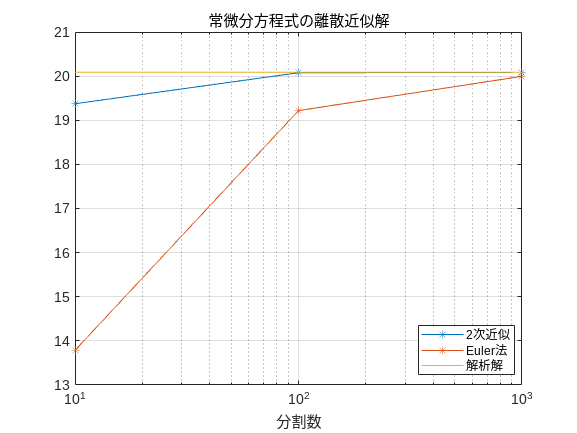

kappas = 3; 
x0 = 1; 
T = 1; 
nStepss = [10;100;1000];
ve = zeros(size(nStepss));
vs = zeros(size(nStepss));
for iloop = 1:size(nStepss,1)
    nSteps = nStepss(iloop);
    dt = T/nSteps;
    xe = x0; 
    xt = x0; 
    for jloop = 1:nSteps
        xe = xe + kappas*xe*dt; 
        xt = xt + kappas*xt*dt + kappas^2*xt*dt^2/2; 
    end
    ve(iloop) = xe; 
    vs(iloop) = xt; 
end
nfig = 12;
figure(nfig); semilogx(nStepss,vs,'*-'); grid; title("常微分方程式の離散近似解"); xlabel("分割数"); hold on;
semilogx(nStepss,ve,'*-'); semilogx(nStepss,exp(kappas*T)*ones(size(nStepss)),'-'); legend("2次近似","Euler法","解析解","Location","best"); hold off;

#### 確率微分方程式の離散化

　解くべき確率微分方程式を

    
$${\rm d}X_t = a(t,X_t){\rm d}t + b(t,X_t) {\rm d}W_t$$


とする。 $W_t$はブラウン運動である。形式的な解は $X_t$を所与とすると、


$$X_{t+\Delta t} = X_t + \int_{t}^{t+\Delta t} a(s,X_s){\rm d} s + \int_{t}^{t+\Delta t} b(s,X_s) {\rm d} W_s$$


となる。最も単純な方法は区間 $[t,t+\Delta t]$において $a(t,X_t), \ b(t,X_t)$を一定とすることである。このとき


$$X_{t+\Delta t} = X_t + a(t,X_t) \Delta t + b(t,X_t) \left(W_{t+\Delta t} - W_t \right)$$


となる。この方法はEuler-Maruyama近似と呼ばれている。

次に常微分方程式と同様に精度を高めるために高次項を含める方法を考える。伊藤の補題より


$${\rm d} a(t,X_t) = \frac{\partial}{\partial t} a(t,X_t) {\rm d}t + \frac{\partial }{\partial x} a(t,X_t) {\rm d}X_t + \frac{1}{2} \frac{\partial^2 }{\partial x^2} a(t,X_t) {\rm d}X_t^2$$



$$= \left[ \frac{\partial }{\partial t} + a(t,X_t) \frac{\partial}{\partial x} + \frac{1}{2}b^2(t,X_t) \frac{\partial^2}{\partial x^2} \right] a(t,X_t) {\rm d} t + b(t,X_t) \frac{\partial }{\partial x} a(t,X_t) {\rm d}W_t$$
 


$$=\mathcal{L}_t a(t,X_t) {\rm d}t + b(t,X_t) \frac{\partial}{\partial x} a(t,X_t){\rm d}W_t$$


となる。ただし、


$$\mathcal{L}_t = \frac{\partial}{\partial t} + a(t,X_t)\frac{\partial }{\partial x} + \frac{1}{2}b^2(t,X_t) \frac{\partial^2}{\partial x^2}$$


である。Euler-Maruyama近似より


$$a(s,X_s) = a(t,X_t) + \mathcal{L}_t a(t,X_t) (s-t) + b(t,X_t) \frac{\partial }{\partial x} a(t,X_t) \left( W_s - W_t \right)$$


となる。同様にして


$$b(s,X_s) = b(t,X_t) + \mathcal{L}_t b(t,X_t) (s-t) + b(t,X_t) \frac{\partial }{\partial x} b(t,X_t) \left(W_s-W_t)$$


となる。これらを形式的な解に代入して整理すると


$$X_{t+\Delta t} = X_t + a(t,X_t)\Delta t + b(t,X_t) \left( W_{t+\Delta t} - W_t \right) + b(t,X_t) \frac{\partial }{\partial x}b(t,X_t) \int_t^{t+\Delta t} \left( W_s - W_t \right) {\rm d}W_s$$



$$+b(t,X_t)\frac{\partial}{\partial x}a(t,X_t) \int_t^{t+\Delta t} (W_s-W_t){\rm d}s + \mathcal{L}_t b(t,X_t) \int_t^{t+\Delta t} (s-t) {\rm d}W_s + \mathcal{L}_t a(t,X_t) \frac{\Delta t^2}{2}$$


となる。さらに、


$$\int_t^{t+\Delta t} \left(W_s - W_t \right) {\rm d}W_s = \frac{1}{2}W_{t+\Delta t}^2 - \frac{1}{2}W_t^2 - \frac{1}{2}\Delta t - W_t (W_{t+\Delta t}-W_t) = \frac{1}{2}\left(W_{t+\Delta t}-W_t\right)^2 - \frac{1}{2}\Delta t$$



$$\int_t^{t+\Delta t} (W_s-W_t) {\rm d}s = \left. s  \left(W_s-W_t\right) \right\vert_t^{t+\Delta t} - \int_t^{t+\Delta t} s {\rm d}W_s = \int_t^{t+\Delta t} (t+\Delta t - s) {\rm d}W_s$$


と計算できるので、代入して整理すると


$$X_{t+\Delta t} = X_t + a(t,X_t)\Delta t+ b(t,X_t)(W_{t+\Delta t } - W_t ) + \frac{1}{2}b(t,X_t) \frac{\partial }{\partial x}b(t,X_t) \left[ \left(W_{t+\Delta t} - W_t \right)^2 - \Delta t \right]$$



$$+\mathcal{L}_t b(t,X_t) \int_t^{t+\Delta t} (s-t) {\rm d} W_s + b(t,X_t)\frac{\partial }{\partial x} a(t,X_t) \int_t^{t+\Delta t} \left( t+ \Delta t - s \right) {\rm d}W_s +\mathcal{L}_t a(t,X_t) \frac{\Delta t^2}{2}$$


となる。 $\Delta t$が十分に小さいとしてIto積分の離散近似を適用すると


$$\int_t^{t+\Delta t} (s-t){\rm d} W_s \simeq 0$$



$$\int_t^{t+\Delta t} (t+\Delta t - s) {\rm d}W_s \simeq \Delta t \left(W_{t+\Delta t} - W_t \right)$$


であるので、


$$X_{t+\Delta t} = X_t + a(t,X_t)\Delta t+ b(t,X_t)(W_{t+\Delta t } - W_t ) + \frac{1}{2}b(t,X_t) \frac{\partial }{\partial x}b(t,X_t) \left[ \left(W_{t+\Delta t} - W_t \right)^2 - \Delta t \right]$$



$$+ b(t,X_t)\frac{\partial }{\partial x} a(t,X_t) \Delta t \left(W_{t+\Delta t} - W_t \right) +\mathcal{L}_t a(t,X_t) \frac{\Delta t^2}{2}$$


となる。 $\Delta t^2$の項が現れるので便宜的に”2次近似”と呼ぶ。

2次近似式の最初の4項はMilstein Method(Scheme)と呼ばれている。Milstein Methodは $\Delta t$の1次項までの近似である。


$$X_{t+\Delta t} = X_t + a(t,X_t)\Delta t+ b(t,X_t)(W_{t+\Delta t } - W_t ) + \frac{1}{2}b(t,X_t) \frac{\partial }{\partial x}b(t,X_t) \left[ \left(W_{t+\Delta t} - W_t \right)^2 - \Delta t \right]$$


例として以下のような対数正規過程を用いる。


$${\rm d}S_t = r S_t {\rm d} t + \sigma S_t {\rm d}W_t$$


$r, \sigma$は定数とする。このとき $a(t,S_t) = rS_t, \ b(t,S_t) = \sigma S_t$であるのでEuler-Maruyama近似、Milstein Method、"2次近似"は以下のようになる。

Euler-Maruyama近似


$$S_{t+\Delta t} = S_t + r S_t \Delta t + \sigma S_t \left(W_{t+\Delta t} - W_t \right)$$


Milstein Method


$$S_{t+\Delta t} = S_t + r S_t \Delta t + \sigma S_t \left(W_{t+\Delta t} - W_t \right) + \frac{1}{2} \sigma^2 S_t \left[\left(W_{t+\Delta t} - W_t \right)^2 - \Delta t \right]$$


"2次近似"


$$S_{t+\Delta t} = S_t + r S_t \Delta t + \sigma S_t \left(W_{t+\Delta t} - W_t \right) + \frac{1}{2} \sigma^2 S_t \left[\left(W_{t+\Delta t} - W_t \right)^2 - \Delta t \right]+r \Delta t \sigma S_t \left(W_{t+\Delta t} - W_t \right) + r^2 S_t \frac{\Delta t^2}{2}$$


対数正規過程には解析解が存在し $S_t = S_0 {\rm e}^{ \left( r - \frac{1}{2}\sigma^2 \right) t + \sigma W_t$である。以下は $r = 0.1, \sigma = 0.5, t = 10, S_0 = 100$として $\mathbb{E}\left[S_t\right]$をEuler-Maruyama近似、Milstein Method, "2次近似"を用いてシミュレーションで求め解析解 $S_0 {\rm e}^{r \times t} = 100 {\rm e}^{1}$と比較している。

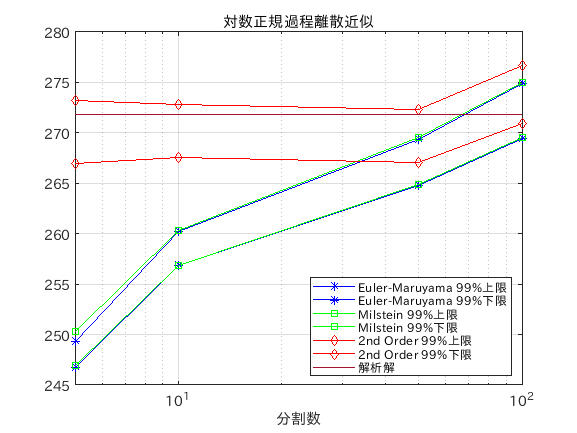

% 対数正規過程　パラメータ設定
r = 0.1; 
sig = 0.5; 
T = 10.0; 
S0 = 100; 

% シミュレーション設定
Nsim = 10000;
Nt = 100; 
alp = 0.01; 

% 分割数
nStepss = [5;10;50;100];

lowerEM = zeros(size(nStepss));
upperEM = zeros(size(nStepss));
lowerMM = zeros(size(nStepss));
upperMM = zeros(size(nStepss));
lowerSO = zeros(size(nStepss));
upperSO = zeros(size(nStepss));

for iloop = 1:size(nStepss,1)
    nSteps = nStepss(iloop);
    dt = T/nSteps;
    valFun = @(S) mean(S);
    mcPricer = @(rngid) logNormalPricier(valFun,S0,r,sig,dt,nSteps,Nsim,rngid);
    vem = zeros(Nt,1);
    vmm = zeros(Nt,1);
    vso = zeros(Nt,1);
    for jloop = 1:Nt
        vals = mcPricer(jloop);
        vem(jloop) = vals.EulerMaruyama;
        vmm(jloop) = vals.MilsteinMethod;
        vso(jloop) = vals.SecondOrder; 
    end
    % Euler-Maruyama Approximation 99% Confidence Interval
    rst = estConfidenceInterval(vem,alp);
    lowerEM(iloop) = rst.CILower;
    upperEM(iloop) = rst.CIUpper;
    
    % Milstein Method 99% Confidence Interval
    rst = estConfidenceInterval(vmm,alp);
    lowerMM(iloop) = rst.CILower; 
    upperMM(iloop) = rst.CIUpper;
    
    % 2nd order Approximation 99% Confidence Interval
    rst = estConfidenceInterval(vso,alp);
    lowerSO(iloop) = rst.CILower;
    upperSO(iloop) = rst.CIUpper; 
    
end
nfig = 13;
figure(nfig);  
semilogx(nStepss,[upperEM,lowerEM],'*b-'); grid; xlabel("分割数"); title("対数正規過程離散近似"); hold on; 
semilogx(nStepss,[upperMM,lowerMM],'sg-'); semilogx(nStepss,[upperSO,lowerSO],'dr-'); semilogx(nStepss,S0*exp(r*T)*ones(size(nStepss)),'-');
legend("Euler-Maruyama 99%上限","Euler-Maruyama 99%下限","Milstein 99%上限","Milstein 99%下限","2nd Order 99%上限","2nd Order 99%下限","解析解","Location","best");
hold off; 

#### プットオプション計算

Black-Scholesモデルでのプットオプションの計算をシミュレーションで行い、解析解と比較する。

シミュレーションでは以下の確率微分方程式を離散化する。離散化の方法の違いによる影響を確認する。


$${\rm d}S_t = r S_t {\rm d} t + \sigma S_t {\rm d}W_t$$


なお、通常は $x_t = \log S_t$と変数変換をして、 $x_t$に関する確率微分方程式を解く(離散化する)。


$${\rm d}x_t = \left(r - \frac{1}{2}\sigma^2\right) {\rm d}t + \sigma {\rm d}W_t$$


ここでは離散化方法の違いを確認するために $S_t$に関する確率微分方程式を離散化する。

プットオプションの満期を1年、ストライクを100とする。初期株価を100とし、金利 $r = 1\%$、ボラティリティ $\sigma = 30 \%$とする。

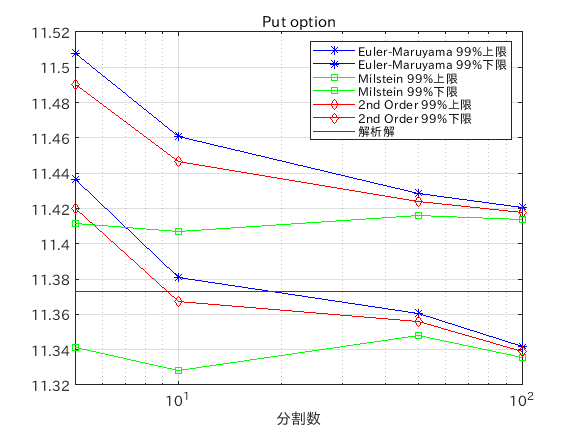

% 対数正規過程　パラメータ設定
r = 0.01; 
sig = 0.3; 
T = 1.0; 
S0 = 100; 
K = 100; 

% 解析解
vana = bsModelCallPut(S0,r,sig,T,K);

% シミュレーション設定
Nsim = 10000;
Nt = 100; 
alp = 0.01; 

% 分割数
nStepss = [5;10;50;100];

lowerEM = zeros(size(nStepss));
upperEM = zeros(size(nStepss));
lowerMM = zeros(size(nStepss));
upperMM = zeros(size(nStepss));
lowerSO = zeros(size(nStepss));
upperSO = zeros(size(nStepss));

valFunImpl = @(S,n,dt) (1/(1+r*dt))^n*mean(max(K-S,0));

for iloop = 1:size(nStepss,1)
    nSteps = nStepss(iloop);
    dt = T/nSteps;
    valFun = @(S) valFunImpl(S,nSteps,dt);
    mcPricer = @(rngid) logNormalPricier(valFun,S0,r,sig,dt,nSteps,Nsim,rngid);
    vem = zeros(Nt,1);
    vmm = zeros(Nt,1);
    vso = zeros(Nt,1);
    for jloop = 1:Nt
        pvs = mcPricer(jloop);
        vem(jloop) = pvs.EulerMaruyama;
        vmm(jloop) = pvs.MilsteinMethod;
        vso(jloop) = pvs.SecondOrder; 
    end
    % Euler-Maruyama Approximation 99% Confidence Interval
    rst = estConfidenceInterval(vem,alp);
    lowerEM(iloop) = rst.CILower;
    upperEM(iloop) = rst.CIUpper;
    
    % Milstein Method 99% Confidence Interval
    rst = estConfidenceInterval(vmm,alp);
    lowerMM(iloop) = rst.CILower; 
    upperMM(iloop) = rst.CIUpper;
    
    % 2nd order Approximation 99% Confidence Interval
    rst = estConfidenceInterval(vso,alp);
    lowerSO(iloop) = rst.CILower;
    upperSO(iloop) = rst.CIUpper; 
    
end

nfig = 14; 
figure(nfig); 
semilogx(nStepss,[upperEM,lowerEM],'*b-'); grid; xlabel("分割数"); title("Put option"); hold on; 
semilogx(nStepss,[upperMM,lowerMM],'sg-'); semilogx(nStepss,[upperSO,lowerSO],'dr-'); semilogx(nStepss,vana.putValue*ones(size(nStepss)),'-');
legend("Euler-Maruyama 99%上限","Euler-Maruyama 99%下限","Milstein 99%上限","Milstein 99%下限","2nd Order 99%上限","2nd Order 99%下限","解析解","Location","best");
hold off;

### 確率微分方程式における微分計算

　次のような確率微分方程式を含む期待値計算を考える。


$${\rm d}X_t = \mu(t,X_t,\theta_1) {\rm d}t + \sigma(t,X_t,\theta_2) {\rm d}W$$



$$v(X_0,\theta_1, \theta_2) = \mathbb{E}\left[ f\left(X_T \right) \right]$$


ただし、確率微分方程式に解析解はなく、 $X_T$の値は離散化してシミュレーションで求めるとする。

このときにパラメータによる微分 $\frac{\partial }{\partial X_0} v(X_0,\theta_1, \theta_2), \frac{\partial }{\partial \theta_1}v(X_0,\theta_1, \theta_2),\frac{\partial }{\partial \theta_2}v(X_0,\theta_1, \theta_2)$は、講義ノートNo.2での微分で示した有限差分法(中心差分で同じ乱数列を使用)で評価することになる。

$X_T$が解析的に表現される場合には、パスごと微分、もしくはlikelihood methodが使える。例えば、Black-Sholesモデル（対数正規過程）は解析的に解けることがよく知られている。

しかし、一般に確率微分方程式が解析的に解けるケースは限られている。解析的に解けない場合にはMalliavin 微分を応用する方法もある（解析的に解ける場合にはlikelihood methodと同じ結果を与える）が、本講義では割愛する。

#### プットオプションの感応度計算

プットオプションの感応度のうちデルタとカッパー／ベガ(ボラティリティ感応度）を中心差分でシミュレーションで計算し、解析解と比較する。

設定はプットオプションの価格計算と同じである。

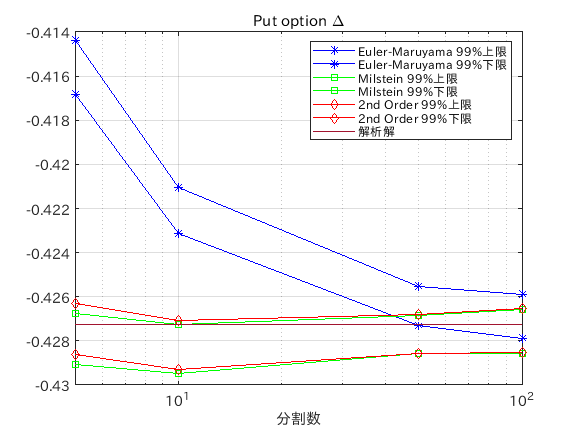

% 対数正規過程　パラメータ設定
r = 0.01; 
sig = 0.3; 
T = 1.0; 
S0 = 100; 
K = 100; 

vana = bsModelCallPut(S0,r,sig,T,K);

% シミュレーション設定
Nsim = 10000;
Nt = 100; 
alp = 0.01; 

% 分割数
nStepss = [5;10;50;100];

lowerDeltaEM = zeros(size(nStepss));
upperDeltaEM = zeros(size(nStepss));
lowerDeltaMM = zeros(size(nStepss));
upperDeltaMM = zeros(size(nStepss));
lowerDeltaSO = zeros(size(nStepss));
upperDeltaSO = zeros(size(nStepss));

lowerKappaEM = zeros(size(nStepss));
upperKappaEM = zeros(size(nStepss));
lowerKappaMM = zeros(size(nStepss));
upperKappaMM = zeros(size(nStepss));
lowerKappaSO = zeros(size(nStepss));
upperKappaSO = zeros(size(nStepss));

valFunImpl = @(S,n,dt) (1/(1+r*dt))^n*mean(max(K-S,0));

dS = 0.01*S0; % デルタ計算用シフト幅
dsig = 0.001; % カッパー計算用シフト幅
for iloop = 1:size(nStepss,1)
    nSteps = nStepss(iloop);
    dt = T/nSteps;
    % payoff関数
    valFun = @(S) valFunImpl(S,nSteps,dt);
    % Simulation
    mcPricer = @(S0,sig,rngid) logNormalPricier(valFun,S0,r,sig,dt,nSteps,Nsim,rngid);
    % mcPricerの戻値による中心差分計算
    calcFD = @(vUp,vDn,dv) [(vUp.EulerMaruyama - vDn.EulerMaruyama)/(2*dv), ...
                            (vUp.MilsteinMethod - vDn.MilsteinMethod)/(2*dv), ...
                            (vUp.SecondOrder - vDn.SecondOrder)/(2*dv)];

    deltaEM = zeros(Nt,1);
    deltaMM = zeros(Nt,1);
    deltaSO = zeros(Nt,1);

    kappaEM = zeros(Nt,1);
    kappaMM = zeros(Nt,1);
    kappaSO = zeros(Nt,1);
    
    for jloop = 1:Nt
        % デルタ計算
        deltas = calcFD(mcPricer(S0+dS,sig,jloop), mcPricer(S0-dS,sig,jloop), dS);
        deltaEM(jloop) = deltas(1);
        deltaMM(jloop) = deltas(2);
        deltaSO(jloop) = deltas(3);
        % カッパー(ベガ）計算
        kappas = calcFD(mcPricer(S0,sig+dsig,jloop), mcPricer(S0,sig-dsig,jloop), dsig);
        kappaEM(jloop) = kappas(1);
        kappaMM(jloop) = kappas(2);
        kappaSO(jloop) = kappas(3);
    end
    % Euler-Maruyama Approximation 99% Confidence Interval
    rst = estConfidenceInterval(deltaEM,alp);
    lowerDeltaEM(iloop) = rst.CILower;
    upperDeltaEM(iloop) = rst.CIUpper;

    rst = estConfidenceInterval(kappaEM,alp);
    lowerKappaEM(iloop) = rst.CILower;
    upperKappaEM(iloop) = rst.CIUpper;
    
    % Milstein Method 99% Confidence Interval
    rst = estConfidenceInterval(deltaMM,alp);
    lowerDeltaMM(iloop) = rst.CILower; 
    upperDeltaMM(iloop) = rst.CIUpper;

    rst = estConfidenceInterval(kappaMM,alp);
    lowerKappaMM(iloop) = rst.CILower;
    upperKappaMM(iloop) = rst.CIUpper;
    
    % 2nd order Approximation 99% Confidence Interval
    rst = estConfidenceInterval(deltaSO,alp);
    lowerDeltaSO(iloop) = rst.CILower; 
    upperDeltaSO(iloop) = rst.CIUpper;

    rst = estConfidenceInterval(kappaSO,alp);
    lowerKappaSO(iloop) = rst.CILower;
    upperKappaSO(iloop) = rst.CIUpper; 
    
end
nfig = 15; 
figure(nfig);
semilogx(nStepss,[upperDeltaEM,lowerDeltaEM],'*b-'); grid; xlabel("分割数"); title("Put option \Delta"); hold on; 
semilogx(nStepss,[upperDeltaMM,lowerDeltaMM],'sg-'); semilogx(nStepss,[upperDeltaSO,lowerDeltaSO],'dr-'); semilogx(nStepss,vana.putDelta*ones(size(nStepss)),'-');
legend("Euler-Maruyama 99%上限","Euler-Maruyama 99%下限","Milstein 99%上限","Milstein 99%下限","2nd Order 99%上限","2nd Order 99%下限","解析解","Location","best");
hold off;

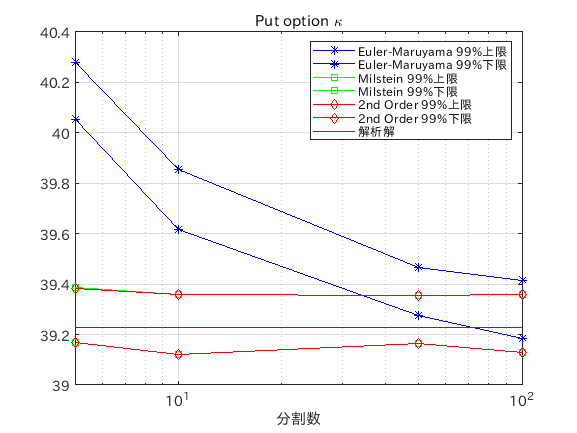


nfig = 16;
figure(nfig);
semilogx(nStepss,[upperKappaEM,lowerKappaEM],'*b-'); grid; xlabel("分割数"); title("Put option \kappa"); hold on; 
semilogx(nStepss,[upperKappaMM,lowerKappaMM],'sg-'); semilogx(nStepss,[upperKappaSO,lowerKappaSO],'dr-'); semilogx(nStepss,vana.Kappa*ones(size(nStepss)),'-');
legend("Euler-Maruyama 99%上限","Euler-Maruyama 99%下限","Milstein 99%上限","Milstein 99%下限","2nd Order 99%上限","2nd Order 99%下限","解析解","Location","best");
hold off;

**課題**

 $x_t = \log S_t$と変数変換をして、 $x_t$に関する確率微分方程式を離散化してシミュレーションを行い、上の例のPutオプションの価格、Δ、κを推定せよ。

なお、 $x_t$が従う確率微分方程式は


$${\rm d}x_t = \left(r - \frac{1}{2}\sigma^2\right) {\rm d}t + \sigma {\rm d}W_t$$


であり、離散化して解く場合には


$$x_{t+\Delta t} = x_t + \left(r - \frac{1}{2}\sigma^2 \right) \Delta t + \sigma \left( W_{t+\Delta t} - W_t \right)$$


となる。これは離散近似ではなく離散時間グリッドでの解であることに注意する。誤差は純粋にモンテカルロ誤差だけである。 

解答例

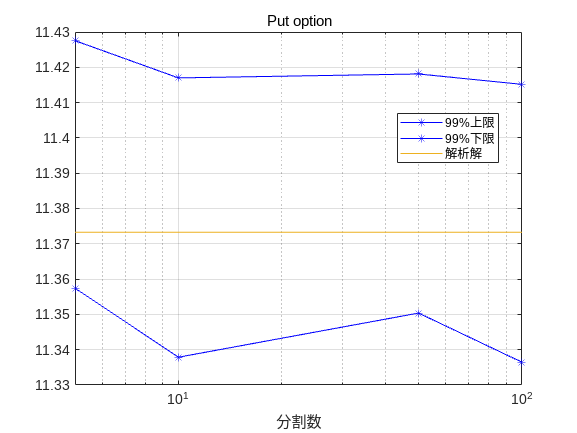

clear; 

% 対数正規過程　パラメータ設定
r = 0.01; 
sig = 0.3; 
T = 1.0; 
S0 = 100; 
K = 100; 

vana = bsModelCallPut(S0,r,sig,T,K);

% シミュレーション設定
Nsim = 10000;
Nt = 100; 
alp = 0.01; 

% 分割数
nStepss = [5;10;50;100];

lower = zeros(size(nStepss));
upper = zeros(size(nStepss));
lowerDelta = zeros(size(nStepss));
upperDelta = zeros(size(nStepss));
lowerKappa = zeros(size(nStepss));
upperKappa = zeros(size(nStepss));


valFunImpl = @(S,n,dt) (1/(1+r*dt))^n*mean(max(K-S,0));

dS = 0.01*S0; % デルタ計算用シフト幅
dsig = 0.001; % カッパー計算用シフト幅
for iloop = 1:size(nStepss,1)
    nSteps = nStepss(iloop);
    dt = T/nSteps;
    % payoff関数
    valFun = @(S) valFunImpl(S,nSteps,dt);
    % Simulation
    mcPricer = @(S0,sig,rngid) logNormalPricier(valFun,S0,r,sig,dt,nSteps,Nsim,rngid);
    % mcPricerの戻値による中心差分計算
    calcFD = @(vUp,vDn,dv) (vUp.Exact - vDn.Exact)/(2*dv);

    vals = zeros(Nt,1);
    deltas = zeros(Nt,1);
    kappas = zeros(Nt,1);
    
    for jloop = 1:Nt
        % 価格計算
        v = mcPricer(S0,sig,jloop);
        vals(jloop) = v.Exact; 
        % デルタ計算
        deltas(jloop) = calcFD(mcPricer(S0+dS,sig,jloop), mcPricer(S0-dS,sig,jloop), dS);
        % カッパー(ベガ）計算
        kappas(jloop) = calcFD(mcPricer(S0,sig+dsig,jloop), mcPricer(S0,sig-dsig,jloop), dsig);
    end
    % Put option value 99% Confidence Interval
    rst = estConfidenceInterval(vals,alp);
    lower(iloop) = rst.CILower;
    upper(iloop) = rst.CIUpper;
    
    % Put option delta 99% Confidence Interval
    rst = estConfidenceInterval(deltas,alp);
    lowerDelta(iloop) = rst.CILower; 
    upperDelta(iloop) = rst.CIUpper;
    
    % Put option 99% Confidence Interval
    rst = estConfidenceInterval(kappas,alp);
    lowerKappa(iloop) = rst.CILower;
    upperKappa(iloop) = rst.CIUpper; 
    
end
nfig = 17; 
figure(nfig); 
semilogx(nStepss,[upper,lower],'*b-'); grid; xlabel("分割数"); title("Put option");hold on; 
semilogx(nStepss,vana.putValue*ones(size(nStepss)),'-');
legend("99%上限","99%下限","解析解","Location","best");
hold off;

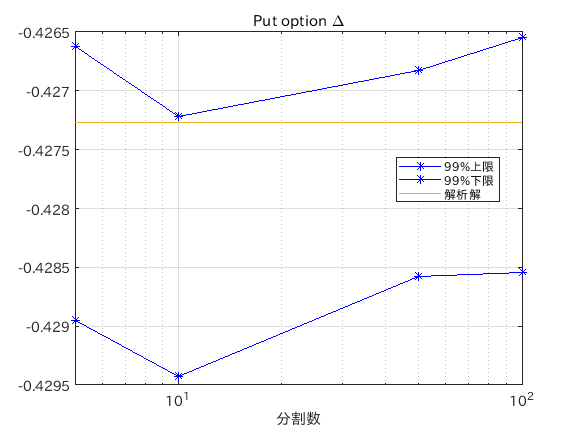


nfig = 18; 
figure(nfig);
semilogx(nStepss,[upperDelta,lowerDelta],'*b-'); grid; xlabel("分割数"); title("Put option \Delta"); hold on; 
semilogx(nStepss,vana.putDelta*ones(size(nStepss)),'-');
legend("99%上限","99%下限","解析解","Location","best");
hold off;

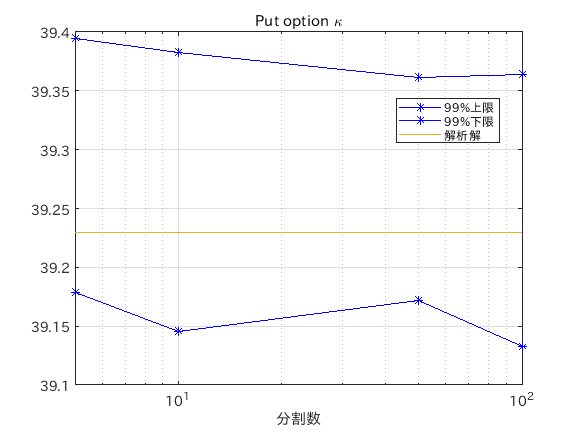


nfig = 19;
figure(nfig);
semilogx(nStepss,[upperKappa,lowerKappa],'*b-'); grid; xlabel("分割数"); title("Put option \kappa"); hold on; 
semilogx(nStepss,vana.Kappa*ones(size(nStepss)),'-');
legend("99%上限","99%下限","解析解","Location","best");
hold off;

## ローカル関数

対数正規過程

function rsts = logNormalPricier(valFun,S0,r,sig,dt,nSteps,Nsim,rngId)
    % 対数正規過程のパスシミュレーション
    % 離散近似方法としてEuler-Maruyama, Milstein, 2次近似を同時に行う
    % シミュレーション最終時点でのvalFun(S)の値を返す
    arguments
        valFun (1,1) function_handle % payoff 関数 double -> double
        S0 (1,1) {mustBeReal,mustBePositive} % 初期株価
        r (1,1) {mustBeReal} % ドリフト
        sig (1,1) {mustBeReal} % ボラティリティ
        dt (1,1) {mustBeReal,mustBePositive}
        nSteps (1,1) {mustBeInteger,mustBePositive}
        Nsim (1,1) {mustBeInteger,mustBePositive}
        rngId (1,1) {mustBeInteger,mustBePositive}
    end
    
    rng(rngId); 
    x = log(S0);
    Sem = S0;
    Smm = S0;
    Sso = S0; 
    rdt = r*dt; 
    xdrft = rdt - 0.5*sig^2*dt; 
    for kloop = 1:nSteps
        % ブラウン運動
        dw = sqrt(dt)*randn(Nsim,1);
        
        % x = log(S)での1step
        x = x + xdrft + sig*dw; 

        % Euler-Maruyama近似での1ステップ発展オペレーター
        emOp = 1 + rdt + sig*dw;
        % Milstein近似での1ステップ発展オペレーター
        mmOp = emOp + 0.5*sig^2*(dw.^2-dt); 
        % 2次近似での1ステップ発展オペレーター
        soOp = mmOp + rdt*dw + 0.5*rdt*rdt;

        % Euler-Maruyama Approximation
        Sem = emOp.*Sem;
        % Milstein Method
        Smm = mmOp.*Smm;
        % 2nd Order Approximation
        Sso = soOp.*Sso;
    end
    rsts.Exact = valFun(exp(x));
    rsts.EulerMaruyama = valFun(Sem);
    rsts.MilsteinMethod = valFun(Smm);
    rsts.SecondOrder = valFun(Sso);
end